# 2 DOF Cell Model in plane strain

## Data

% 
clearvars; close all; clc;
set_env;

addpath("2DOF\");
addpath("1DOF\");
load('cell_2dof.mat')
load('cell_2dof_pstrain.mat')
load('1DOF\cell_1dof_pstrain.mat')

% Data --------------------------------------------------------------
epsilon1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 l_c w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms V F

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)

## Equations

% Equations ---------------------------------------------------------
makeassumptions
% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / (l_0 - l_c) == (dtf / 2) / (l_0 - l_c - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-l_{c}-\xi +\xi_{0}\right)}{l_{0}-l_{c}}$$

t_f(x) = tf_0 + dt_f;
% limit(t_f(x), l_c, l_0)

w = pstrain_2dof.w

$$w = w_{0}$$

t_p = pstrain_2dof.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

l_a = pstrain_2dof.l_a

$$l\_a = l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}$$

A1 = pstrain_2dof.A1

$$A1 = l_{c}\,w_{0}$$

A2 = pstrain_2dof.A2

$$A2 = w_{0}\,\left(l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)$$

C1_str = pstrain_2dof.C1

$$C1\_str = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

C2_str = pstrain_2dof.C2

$$C2\_str = \frac{\log\left(-\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-l_{c}\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\epsilon_{f}\,l_{0}\,w_{0}\,\epsilon_{1}\left(x\right)-\epsilon_{f}\,l_{c}\,w_{0}\,\epsilon_{1}\left(x\right)\right)}{{\mathrm{tf}}_{0}-x}-\frac{\log\left(\epsilon_{p}\,\left(l_{0}-l_{c}\right)\,\left({\mathrm{tf}}_{0}-x\right)-\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-l_{c}\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\epsilon_{f}\,l_{0}\,w_{0}\,\epsilon_{1}\left(x\right)-\epsilon_{f}\,l_{c}\,w_{0}\,\epsilon_{1}\left(x\right)\right)}{{\mathrm{tf}}_{0}-x}$$

Vol_0 = pstrain_2dof.Vol_0                 

$$Vol\_0 = l_{0}\,{\mathrm{tp}}_{0}\,w_{0}$$


pstrain = sstrain2(pstrain_2dof, "PSTRAIN");
Vol = pstrain.Vol

$$Vol = l_{c}\,{\mathrm{tf}}_{0}\,w_{0}+\frac{w_{0}\,\left({\mathrm{tf}}_{0}+x\right)\,\left(l_{0}-l_{c}\right)}{2}+2\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)+2\,l_{c}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)$$

C1 = pstrain.C1

$$C1 = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

C2 = pstrain.C2

$$C2 = \frac{\log\left(-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\frac{\epsilon_{f}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,\left(l_{0}-l_{c}\right)}-\frac{\epsilon_{f}\,l_{c}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)}\right)}{{\mathrm{tf}}_{0}-x}-\frac{\log\left(\epsilon_{p}\,\left(l_{0}-l_{c}\right)\,\left({\mathrm{tf}}_{0}-x\right)-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w_{0}-\epsilon_{f}\,l_{c}\,w_{0}+\frac{\epsilon_{f}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,\left(l_{0}-l_{c}\right)}-\frac{\epsilon_{f}\,l_{c}\,w_{0}\,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)}\right)}{{\mathrm{tf}}_{0}-x}$$

Uel = pstrain.Uel

$$Uel(x) = -\frac{Y_{p}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)\,{\left({\mathrm{tf}}_{0}-x\right)}^{4}}{64\,{l_{0}}^{2}\,\left(\nu^{2}-1\right)\,{\left(l_{0}-l_{c}\right)}^{2}}$$


% pstrain.A1 = l_c * pstrain.w; 
% C1 = (1 / pstrain.Cf1 + 2 / (pstrain.A1 * epsilon_p / pstrain.t_p))^(-1)
% makeassumptions
% fprintf("C1 as x -> tf_0 \n")
% simplify(limit(C1, x, tf_0))
% fprintf("C1 as l_c -> l_0 \n")
% simplify(limit(C1, l_c, l_0))
% fprintf("C1 as l_c -> 0 \n")
% simplify(limit(C1, l_c, 0))
% 
% C2 = simplify(pstrain.C2)
% makeassumptions
% fprintf("C2 as x -> tf_0 \n")
% simplify(limit(sstrain2(C2), x, tf_0))
% fprintf("C2 as l_c -> l_0 \n")
% simplify(limit(sstrain2(C2), l_c, l_0))
% fprintf("C2 as l_c -> l_0, x -> tf_0 \n")
% simplify(limit(ans, x, tf_0))
% fprintf("C2 as l_c -> 0 \n")
% simplify(limit(sstrain2(C2) , l_c, 0))
% fprintf("C1 1 DOF\n")
% res_1dof_pstrain.C

% myfig(1, "C 1DOF - $C_2$ 2DOF with $l_c$ = 0"); hold on; grid on;
% fplot(x,sdata2(simplify(limit(sstrain2(C2) , l_c, 0))), [double(sdata2(tf_0)) , 10e-3], 'LineWidth', 1.5, 'DisplayName', "$C_2$ 2DOF")
% fplot(x,sdata2(res_1dof_pstrain.C), [double(sdata2(tf_0)) , 10e-3], '--', 'LineWidth', 1.5, 'DisplayName', "C 1DOF")
% legend("Location","northeast")
% title("C 1DOF - $C_2$ 2DOF with $l_c$ = 0")
% xlabel("x [m]")
% ylabel("C(x) [F]")

% Range limit
x_min = sdata2(tf_0)

$$x\_min = \frac{1}{100000}$$

x_max = sdata2(rhs(isolate(sstrain2(epsilon_1(x)) == epsilon1_max, x)))

$$x\_max = \frac{\sqrt{2}\,\sqrt{5}\,\sqrt{40}\,\sqrt{\frac{1}{40}-l_{c}}}{200}+\frac{1}{100000}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C = C1

$$C = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)}{\epsilon_{p}\,l_{c}\,w_{0}}}$$


% Min capacitance
Cmin = vpa(sdata2(limit(C, x, x_max)),4);

% Max capacitance
Cmax = vpa(sdata2(limit(C, x, tf_0)),4);


## Elastic energy

Uel

$$Uel(x) = -\frac{Y_{p}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\frac{\nu \,{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}\,\left(l_{0}-l_{c}\right)\,\left(\nu -1\right)}+1\right)\,\left(l_{0}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)\,{\left({\mathrm{tf}}_{0}-x\right)}^{4}}{64\,{l_{0}}^{2}\,\left(\nu^{2}-1\right)\,{\left(l_{0}-l_{c}\right)}^{2}}$$

## Equations

eq_diffx = diff(Uel, x) - V^2 /2 * diff(C1, x) == F;
eq_difflc = diff(Uel,l_c) - V^2 /2 * diff(C1, l_c) == 0;
eq_x = sdata2(eq_diffx);
eq_lc = sdata2(eq_difflc);

## Solution

x_range = double(linspace(x_min+1e-8, 7e-3, 15))';
V_range = [0.1 1000:1000:6000];
sol_lc = cell(1, length(V_range));
sol_F = cell(1, length(V_range));
sol_C1 = cell(1, length(V_range));
tic 
for i = 1:length(V_range)
    eq_lc_tmp = subs(eq_lc, V, V_range(i));
    s_tmp = double(sdata2(l_0));
    for j = 1:length(x_range)
        s = double(vpasolve(subs(eq_lc_tmp, x, x_range(j))));
        % s(imag(s) == 0 & s <= sdata2(l_0))
        if s(1) <= 0 && isreal(s(1))
            s(1) = 1e-7;
        end
        sol_lc{i}(j) = s(1);
        sol_F{i}(j) = double(lhs(subs(eq_x, {V, l_c, x}, {V_range(i), sol_lc{i}(j), x_range(j)})));
        sol_C1{i}(j) = double(subs(sdata2(C1), {V, l_c, x}, {V_range(i), sol_lc{i}(j), x_range(j)}));
        % s_tmp = sol_lc{i}(j);
    end
end
toc

Elapsed time is 36.337069 seconds.


## Zipped length - Capacitance - Force

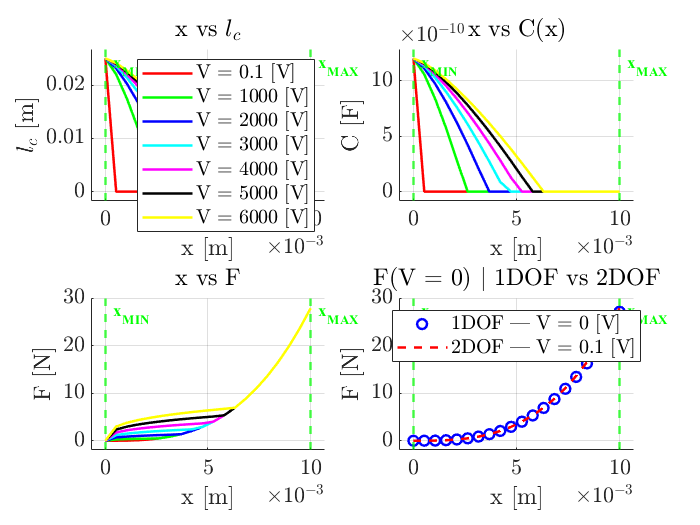

myfig(1, "")
subplot(2,2,1); hold on
for i = 1:length(V_range)
    plot(x_range, sol_lc{i}, plcol(i), 'LineWidth', 1.5,'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
end
plot_xminmax(x_range(1), x_range(end))
legend('Location','east');
addlabels("x [m]", "$l_c$ [m]", "x vs $l_c$")
xlim("padded"); ylim("padded")

subplot(2,2,2); hold on
for i = 1:length(V_range)
    plot(x_range, sol_C1{i}, plcol(i), 'LineWidth', 1.5,'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "C [F]", "x vs C(x)")
xlim("padded"); ylim("padded")

subplot(2,2,3); hold on
for i = 1:length(V_range)
    plot(x_range, sol_F{i}, plcol(i), 'LineWidth', 1.5,'DisplayName', ['V = ' num2str(V_range(i)) ' [V]'])
end
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "F [N]", "x vs F")
xlim("padded"); ylim("padded")

subplot(2,2,4); hold on
plot(x_range, subs(sdata1(pstrain_1dof.FVmin, "PSTRAIN"), x, x_range), 'ob', 'LineWidth', 1.5, 'DisplayName', '1DOF | V = 0 [V]') 
plot(x_range, sol_F{1}, [plcol(1), '--'], 'LineWidth', 1.5,'DisplayName', ['2DOF | V = ' num2str(V_range(1)) ' [V]']) 
plot_xminmax(x_range(1), x_range(end))
addlabels("x [m]", "F [N]", "F(V = 0) $\vert$ 1DOF vs 2DOF")
legend('Location', 'best')
xlim("padded"); ylim("padded")

## Elastic energy from x - F, varying x_max

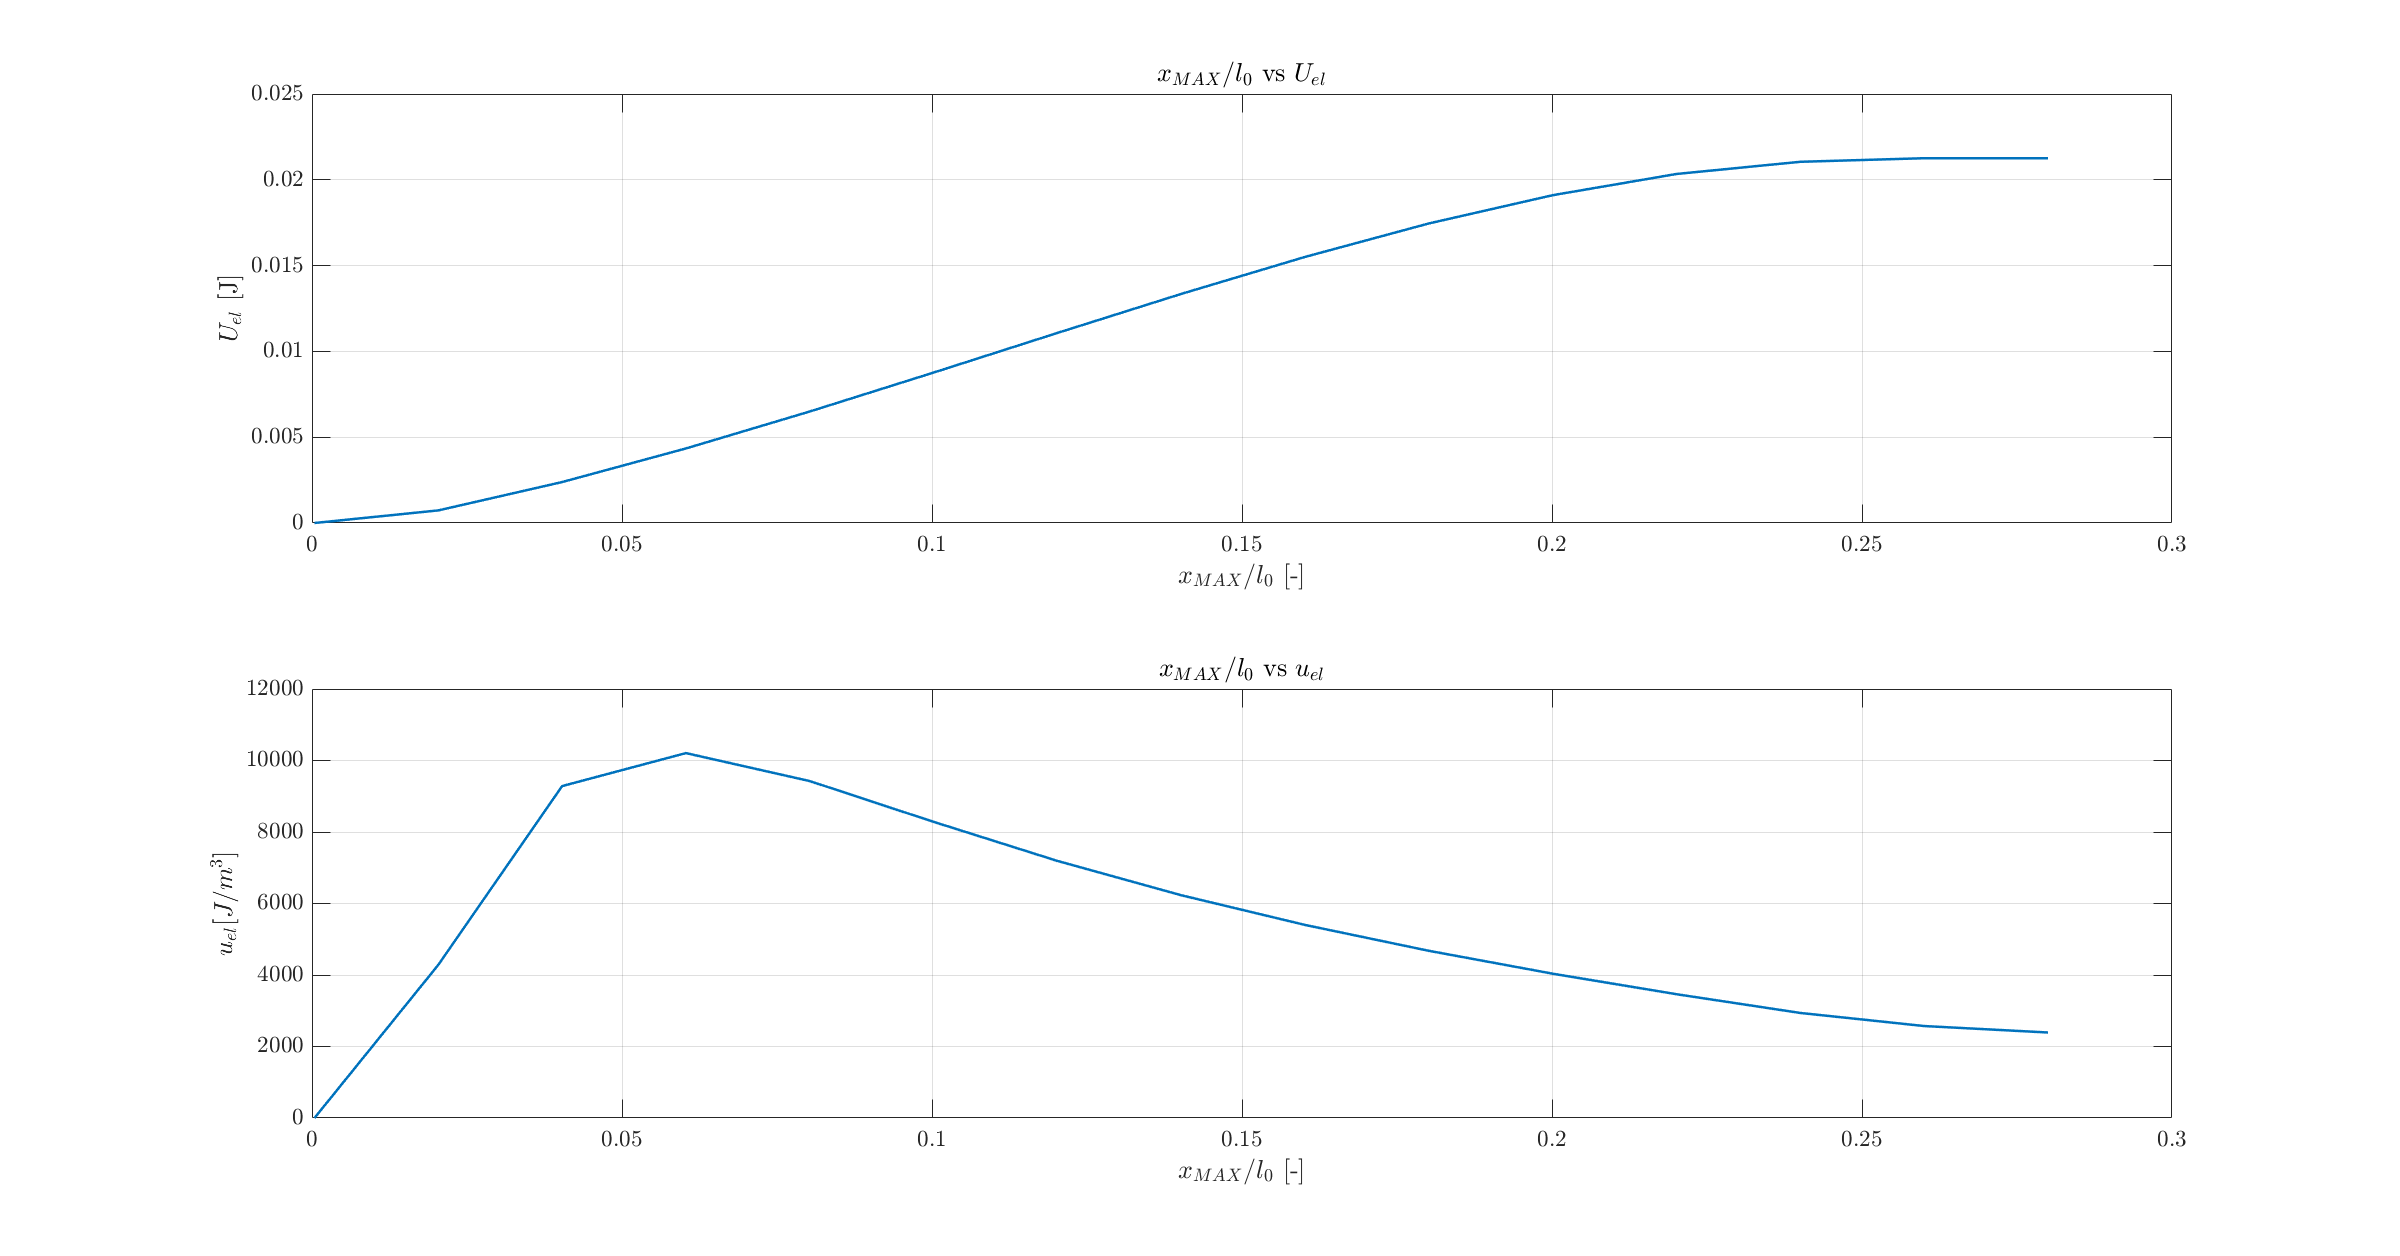

Uel_xmax = zeros(length(x_range),1);
uel_xmax = zeros(length(x_range),1);
Voltmp = sdata2(Vol);
for i = 1:length(x_range)
    Uel_xmax(i) = trapz(x_range(1:i), sol_F{end}(1:i),2) - trapz(x_range(1:i), sol_F{1}(1:i),2);
    uel_xmax(i) = Uel_xmax(i) / double(subs(Voltmp, {x,l_c}, {x_range(i), sol_lc{end}(i)}));
end

myfig(2, "U_{el} and u_{el}");
subplot(2,1,1)
plot(x_range / sdata2(l_0), Uel_xmax, 'LineWidth', 1.5)
addlabels("$x_{MAX} / l_0$ [-]", "$U_{el}$ [J]", "$x_{MAX} / l_0$ vs $U_{el}$")

subplot(2,1,2)
plot(x_range / sdata2(l_0), uel_xmax, 'LineWidth', 1.5)
addlabels("$x_{MAX} / l_0$ [-]", "$u_{el} [J/m^3]$", "$x_{MAX} / l_0$ vs $u_{el}$")

## Q - V

% % Plot Q - V
% C_vec = subs(sdata(C, 1), x_range);
% Vmax_vec = subs(sdata(Vmax, 1), x_range);
% Q_vec = C_vec .* Vmax_vec;
% 
% [V_maxstr_min, idx] = min(Q_vec ./ Cmin);
% x_min_maxstr = x_range(idx);
% 
% [V_minstr_min, idx] = min(Q_vec ./ Cmax);
% x_min_minstr = x_range(idx);

% myfig(4,"Q - V"); clf
% hold on
% plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
% plot(Q_vec, Q_vec ./ Cmax, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
% plot(Q_vec, Q_vec ./ Cmin, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
% legend('Location','best')
% xlabel("Q [A]")
% ylabel("V [V]")
% % ylim([0,max(Vmax_vec)])
% title("Q - V")
% hold off
% 


% sol_C2 = cell(1, length(V_range));
% sol_C = cell(1, length(V_range));
% tmpC2 = sdata2(C2);
% for i = 1:length(V_range)
%     for j = 1:length(x_range)
%         sol_C2{i}(j) = double(subs(tmpC2, {x, l_c}, {x_range(j), sol_lc{i}(j)}));
%         sol_C{i}(j) = sol_C1{i}(j) + sol_C2{i}(j);
%     end
% end
% myfig(2,""); hold on
% for i = 1:length(V_range)
%     plot(x_range, sol_C1{i}, plcol(i), 'LineWidth', 1.5,'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
%     plot(x_range, sol_C{i}, plcol(i,'--'), 'LineWidth', 1.5,'DisplayName', ['V = '  num2str(V_range(i))  ' [V]'])
% end
% plot_xminmax(x_range(1), x_range(end))
% addlabels("x [m]", "C [F]", "x vs C(x)")
% xlim("padded"); ylim("padded")




















